# Identificazione grey-box dei parametri nel dominio del tempo

## Definizione del sistema da controllare

model_initialization

% Parametri fisici del sistema che stimerà il modello
hm=0.01*[1 1];
cm=[0 0];
k=1000*[1 1];
h=0.2*[1 1];
Jm=2e-2*[1 1];
umax=150*[1; 1];

% Creazione modello stimatore
system_estimate=RoboticSystem_estimate(st,rigid_robot,hm,cm,umax,true,Jm,k,h);
system_estimate.setForwardDynamics(@fdCodegen_mex)

## Legge di moto

max_vel=5;
max_acc=50;
wpts = [0 .1 3 0;0 1 -2 -2];

[tvec,qsp,qsp_d,qsp_dd]=motionlaw(wpts,max_vel,max_acc,st*10);

## Definizione parametri controllore (PD controller grossolano)

aval=-150+[0 -2];
A=[0 1;0 0];
B1=[0;1/(9.3)];
K1=place(A,B1,aval);
B2=[0;1/(7.09)];
K2=place(A,B2,aval);

Kp=diag([K1(1) K2(1)]);
Kv=diag([K1(2) K2(2)]);

## Funzione di costo e ottimizzazione

J=@(x)cost_func(x,tvec,qsp,qsp_d,Kp,Kv,system,system_estimate);

x0=[1,1,1e-3,1e-3,1000,1000,1,1,10,10];
lb = [0.1 0.1 0 0 100 100 0.1 0.1 0.1 0.1];
n_vars=length(x0);
opt=optimoptions('fmincon','Display','iter','StepTolerance',1e-10);

timer_=tic;
x=fmincon(J,x0,[],[],[],[],lb,[],[],opt)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      11    5.896276e+00    0.000e+00    6.176e+11

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x = 	1.0e+03 *

    0.0010    0.0010    0.0000    0.0000    1.0000    1.0000    0.0010    0.0010    0.0100    0.0100



fprintf('Executed in %f second\n',toc(timer_));

Executed in 73.970013 second


## Grafico dei risultati

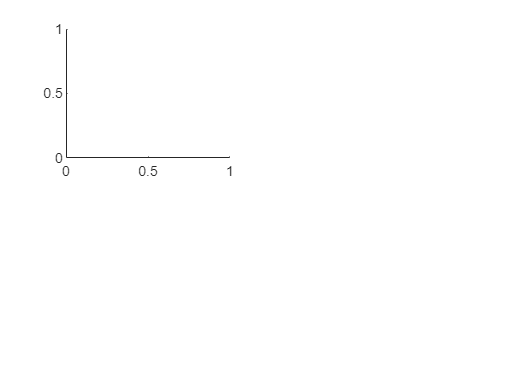

figure
tiledlayout(2,2)
nexttile

plot(tvec,qsp,'--', tvec,q_est, tvec,q)

Unrecognized function or variable 'q_est'.

plot(q(1,:))
hold on
plot(q_est(1,:))
nexttile
plot(q(2,:))
hold on
plot(q_est(2,:))
nexttile
plot(qd(1,:))
hold on
plot(qd_est(1,:))
nexttile
plot(qd(2,:))
hold on
plot(qd_est(2,:))

%{
figure(2)
subplot(4,1,1)
plot(tvec, qsp,'--',tvec,q_est)
xlabel('t')
ylabel('Positions')
legend('X','Y')
subplot(4,1,2)
plot(tvec, qsp_d,'--',tvec, qd_est)
xlabel('t')
ylabel('Velocities')
legend('X','Y')
subplot(4,1,3)
plot(tvec, qsp_dd, tvec, qdd_est)
xlabel('t')
ylabel('Acceleration')
legend('X','Y')
subplot(4,1,4)
plot(tvec, tau)
xlabel('t')
ylabel('Torques')
legend('X','Y')

return
figure
for idx=1:20:length(tvec)
    show(robot,qsp(:,idx));
    drawnow
end
%}

## Sistema identificato

## Validazione